# Perform a voxel-wise t-test

In this example we perform a second level analysis on first level statistical parametric maps. Specifically we use a t-test to obtain an ordinary least squares estimate for the group level parameter. 

The example uses the emotion regulation data provided with CANlab_Core_Tools. This dataset consists of a set of contrast images for 30 subjects from a first level analysis. The contrast is [reappraise neg vs. look neg], reappraisal of negative images vs. looking at matched negative images. 

These data were published in: Wager, T. D., Davidson, M. L., Hughes, B. L., Lindquist, M. A., Ochsner, K. N.. (2008). Prefrontal-subcortical pathways mediating successful emotion regulation. Neuron, 59, 1037-50.

By the end of this example we will have regenerated the results of figure 2A of this paper.

## Executive summary of the whole analysis

As a summary, here is a complete set of commands to load the data and run the entire analysis:

Now, let's walk through it step by step, with a few minor additions.

## Load sample data

% We can load this data using load_image_set(), which produces an fmri_data
% object. Data loading exceeds the scope of this tutorial, but a more
% indepth demosntration may be provided by load_a_sample_dataset.m

[image_obj, networknames, imagenames] = load_image_set('emotionreg');

Loaded images:
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore

## Do a t-test

% Voxel-wise tests estimate parameters for each voxel independently. The
% fmri_data/ttest function performs this just like the native matlab
% ttest() function, and similarly returns a p-value and t-stat. Unlike the
% matlab ttest() function, fmri_data/ttest performs this for every voxel in
% the fmri_data object. All voxels are evaluated independently, but all are
% evaluated nonetheless. A statistic_image is returned.

t = ttest(image_obj);

One-sample t-test
Calculating t-statistics and p-values


## Visualize the results

There are many options. See methods(statistic_image) and methods(region)

orthviews(t)


SPM12: spm_check_registration (v6245)              11:56:55 - 03/08/2018
Display /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


drawnow, snapnow; 

% As can be seen, the ttest() result is unthresholded. The threshold
% function can be used to apply a desired alpha level using any of a number
% of methods. Here FDR is used to control for alpha=0.05. Note that no
% information is erased when performing thresholding on a statistic_image.

t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.002549

Image   1
 27 contig. clusters, sizes   1 to 1472
Positive effect: 2502 voxels, min p-value: 0.00000000
Negative effect:  37 voxels, min p-value: 0.00022793


orthviews(t)


SPM12: spm_check_registration (v6245)              11:56:56 - 03/08/2018
Display /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×27 struct}


drawnow, snapnow; 

% Many neuroimaging packages (e.g., SPM and FSL) do one-tailed tests 
% (with one-tailed p-values) and only show you positive effects 
% (i.e., relative activations, not relative deactivations).  
% All the CANlab tools do two-sided tests, report two-tailed p-values. 
% By default, hot colors (orange/yellow) will show activations, and cool
% colors (blues) show deactivations.


**Extent threshold**

% We can also apply an "extent threshold" of > 10 contiguous voxels:

t = threshold(t, .05, 'fdr', 'k', 10);

Image   1 FDR q < 0.050 threshold is 0.002549

Image   1
  9 contig. clusters, sizes  10 to 1472
Positive effect: 2460 voxels, min p-value: 0.00000000
Negative effect:  32 voxels, min p-value: 0.00022793


orthviews(t)


SPM12: spm_check_registration (v6245)              11:56:58 - 03/08/2018
Display /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×9 struct}


drawnow, snapnow; 

**Slice montages**

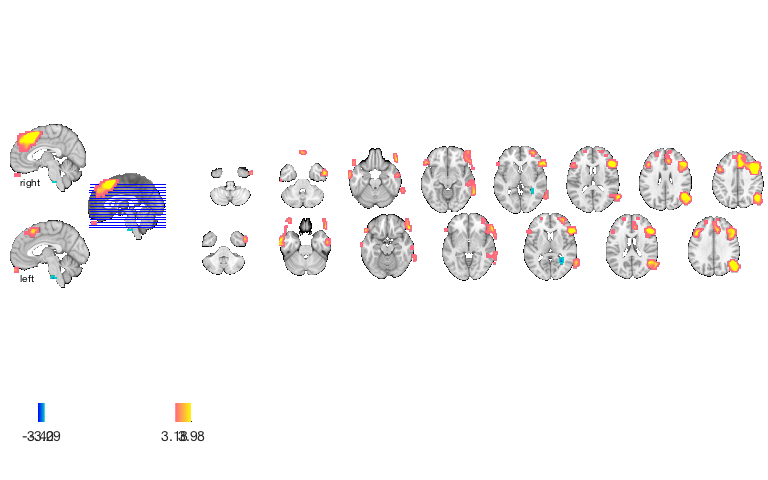

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.


Grouping contiguous voxels:   9 regions
sagittal montage:  31 voxels displayed, 2461 not displayed on these slices
sagittal montage:  97 voxels displayed, 2395 not displayed on these slices
sagittal montage:  76 voxels displayed, 2416 not displayed on these slices
axial montage: 808 voxels displayed, 1684 not displayed on these slices
axial montage: 904 voxels displayed, 1588 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


% montage is another visualization method. This function may require a
% relatively large amount of memory, depending on the resolution of the 
% anatomical underlay image you use. We recommend around 8GB of free memory. 
%
create_figure('montage'); axis off
montage(t)

drawnow, snapnow;

## Print a table of results

% First, we'll have to convert to another object type, a "region object".
% This object groups voxels together into "blobs" (often of contiguous
% voxels). It does many things that other object types do, and inter-operates
% with them closely.  See methods(region) for more info.

% Create a region object called "r", with contiguous blobs from the
% thresholded t-map:

r = region(t);

Grouping contiguous voxels:   9 regions



% Print the table:

table(r);


____________________________________________________________________________________________________________________________________________
Positive Effects
          Region            Volume             XYZ            maxZ     modal_label_descriptions    Perc_covered_by_label    Atlas_regions_covered    region_index
    __________________    __________    _________________    ______    ________________________    _____________________    _____________________    ____________

    'Ctx_TE1a_R'                9864     55      0    -27    3.9997     'Cortex_Default_ModeA'              30                        2                   1      
    'Multiple regions'         57152     55    -58     23    4.7899     'Cortex_De

## More on getting help

% Help info is available on https://canlab.github.io/
% and in the CANlab help examples repository: https://github.com/canlab/CANlab_help_examples
% This contains a series of walkthroughs, including this one.

% You can get help for the main object types by typing this in Matlab:
% doc fmri_data (or doc any other object types)

% Also, more detailed help is available for each function using the "help" command.
% You can get help and options for any object method, like "table". But
% because the method names are simple and often overlap with other Matlab functions 
% and toolboxes (this is OK for objects!), you will often want to specify
% the object type as well, as follows:

help region.table

  Print a table of all regions in a region object (cl). Return labeled
  clusters (separated by those with positive and negative peak values) and
  a Matlab table object with the relevant information.
 
  :Usage:
  ::
 
     [poscl, negcl] = table(cl, [optional inputs])
 
  :Optional inputs:
 
    **k:**
         Print only regions with k or more contiguous voxels
 
    **nosep:**
         do not separate cl with pos and neg effects based on peak in .val
 
    **names:**
         name clusters manually before printing to table and output; saves in .shorttitle field
 
    **forcenames:**
         force manual naming of cl by removing existing names in .shorttitle field
 
  :Outputs:
 
    Returns region objects for cl with pos and neg effects
    - autolabeled if Neuroimaging_Pattern_Masks and atlas tools are available on Matlab path
    - limited by size if entered
    - manually named if requested (see optional inputs)
 
  ..
      Author and copyright information:
 
      Copyright (

## Write the t-map to disk

% Now we need to save our results. You can save the objects in your
% workspace or you can write your resulting thresholded map to an analyze
% file. The latter may be useful for generating surface projections using 
% Caret or FreeSurfer for instance.
%
% Thresholding did not actually eliminate nonsignificant voxels from our 
% statistic_image object (t). If we  simply write out that object, we will 
% get t-statistics for all voxels. 

t.fullpath = fullfile(pwd, 'example_t_image.nii');
write(t)

Writing: 
/Users/torwager/Documents/GitHub/example_t_image.nii



% If we use the 'thresh' option, we'll write thresholded values:
write(t, 'thresh')

Writing thresholded statistic image.
Writing: 
/Users/torwager/Documents/GitHub/example_t_image.nii



t_reloaded = statistic_image(t.fullpath, 'type', 'generic');
orthviews(t_reloaded)


SPM12: spm_check_registration (v6245)              11:57:12 - 03/08/2018
Display /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Displaying image   1, 2492 voxels: example_t_image.nii


ans = 1×1 cell array
    {1×9 struct}


Edited/commented by Bogdan Petre on 9/14/2016 and by Tor Wager, July 2018 